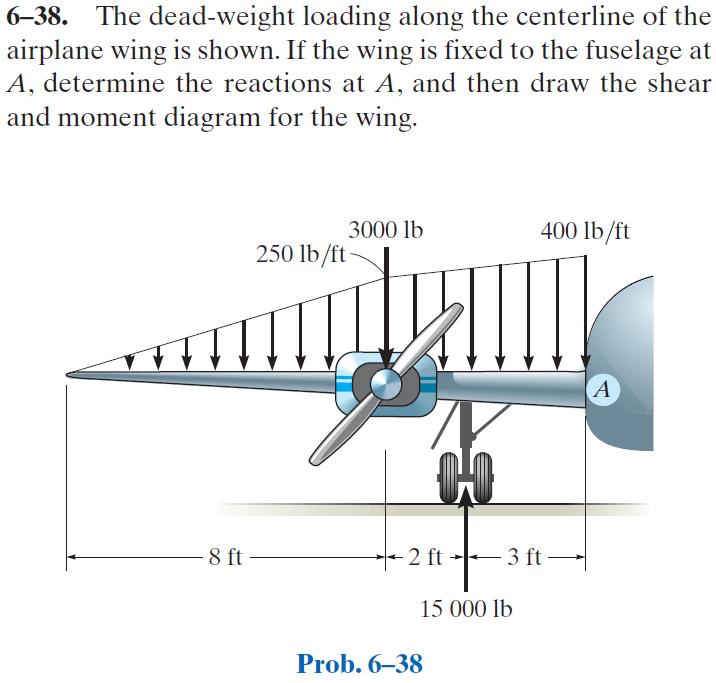

[https://www.chegg.com/homework-help/mechanics-of-materials-8th-edition-solutions-9780136022305](https://www.chegg.com/homework-help/mechanics-of-materials-8th-edition-solutions-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# distributed load formulas

w1 = findpoly(1, 'thru', [0 0], 'thru', [8*u.ft -250*u.lbf/u.ft]);
w2 = findpoly(1, 'thru', [8*u.ft -250*u.lbf/u.ft], 'thru', [13*u.ft -400*u.lbf/u.ft]);

# beam

b = beam;
b = b.add('concentrated', 'force', -3000*u.lbf, 8*u.ft);
b = b.add('concentrated', 'force', 15000*u.lbf, 10*u.ft);
b = b.add('reaction', 'force', 'Ra', 13*u.ft);
b = b.add('reaction', 'moment', 'Ma', 13*u.ft);
b = b.add('distributed', 'force', w1, [0 8]*u.ft);
b = b.add('distributed', 'force', w2, [8 13]*u.ft, [false true]);
b.L = 13*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{25\,\left(x^{5}-27480\,x\,{\mathrm{ft}}^{4}+5272\,{\mathrm{ft}}^{5}\right)}{96\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{3\,x^{5}+5\,x^{4}\,\mathrm{ft}+5920\,x^{3}\,{\mathrm{ft}}^{2}-143360\,x^{2}\,{\mathrm{ft}}^{3}+1063565\,x\,{\mathrm{ft}}^{4}-3051429\,{\mathrm{ft}}^{5}}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\in \left(8\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{{\left(x-13\,\mathrm{ft}\right)}^{2}\,\left(3\,x^{3}+83\,x^{2}\,\mathrm{ft}-22429\,x\,{\mathrm{ft}}^{2}+159459\,{\mathrm{ft}}^{3}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{125\,\left(5496\,{\mathrm{ft}}^{4}-x^{4}\right)}{96\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{5\,\left(3\,x^{4}+4\,x^{3}\,\mathrm{ft}+3552\,x^{2}\,{\mathrm{ft}}^{2}-57344\,x\,{\mathrm{ft}}^{3}+212713\,{\mathrm{ft}}^{4}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\in \left(8\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{5\,\left(x-13\,\mathrm{ft}\right)\,\left(3\,x^{3}+43\,x^{2}\,\mathrm{ft}-13889\,x\,{\mathrm{ft}}^{2}+122099\,{\mathrm{ft}}^{3}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{125\,x^{3}}{24}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{5\,\left(3\,x^{3}+3\,x^{2}\,\mathrm{ft}+1776\,x\,{\mathrm{ft}}^{2}-14336\,{\mathrm{ft}}^{3}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\in \left(8\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{5\,\left(3\,x^{3}+3\,x^{2}\,\mathrm{ft}-7224\,x\,{\mathrm{ft}}^{2}+75664\,{\mathrm{ft}}^{3}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{125\,x^{2}}{8}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -5\,\left(3\,x^{2}+2\,x\,\mathrm{ft}+592\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\in \left(8\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -5\,\left(x-28\,\mathrm{ft}\right)\,\left(3\,x+86\,\mathrm{ft}\right)\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{125\,x}{4}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -10\,\left(3\,x+\mathrm{ft}\right)\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra, 7) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ma} & 18583.33\,\mathrm{ft}\,\mathrm{lbf}\\ \mathrm{Ra} & -9375.0\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

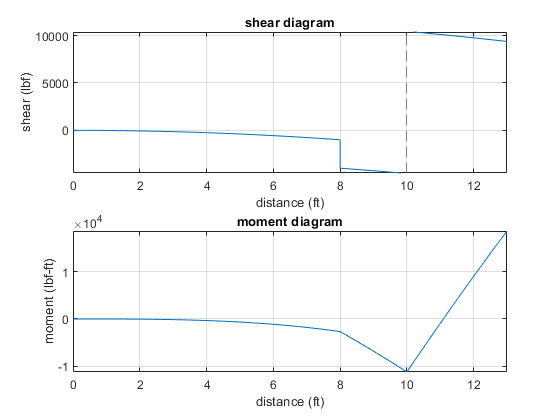

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;